## Logit - Metropolis-Hastings algorithm

### Load data to use:

Apply the program to the Mroz dataset on female labor market participation (mroz.csv) 

% Specify the file path
filePath = "mroz.csv";

% Read the CSV file into a table
mrozTable = readtable(filePath);

% remove the missing value from the dataset
% mrozTable = rmmissing(mrozTable);

% Get the size of the dataset
datasetsize = size(mrozTable);

% Display the size of the dataset
disp(['Number of Rows: ', num2str(datasetsize(1))]);      % 753

Number of Rows: 753


disp(['Number of Columns: ', num2str(datasetsize(2))]);   % 22

Number of Columns: 22


### Generate the y and X for the Logit model:

For a logit model, we assume


$$y_i = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i , \quad i = 1, \ldots, n$$


with $u_i \overset{iid}{\sim} \mathcal{N}(0, \sigma^2)$. In matrix form, this can be written as$y = X\beta + u$ where $y = (y_1, \ldots, y_n)$, $u = (u_1, \ldots, u_n)$ and 


$$X=\left\lbrack \begin{array}{ccccc}
1 & x_{11}  & x_{21}  & \cdots  & x_{\textrm{p1}} \\
1 & x_{12}  & x_{22}  & \cdots  & x_{\textrm{p2}} \\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots \\
1 & x_{1n}  & x_{2n}  & \cdots  & x_{\textrm{pn}} 
\end{array}\right\rbrack$$


Then, we generate the dependent variable and independent variables X based on above form.

For the data, we will use:

    dependend varibale y: whether an individual was approved for a mortgage loan (approve)

    independent variable: 

- income aside from wage (nwifeinc)

- level of education (educ), 

- years of experience and its square (exper), 

- square of years of experience (exper2)

- age (age), 

- number of children less than 6 years of age (kidslt6),

- and number of children between 6 and 18 years of age (kidsge6)

We will have p = 7 and n equal to the the length of y vector.

% generate y
y_Data = mrozTable(:, 'inlf');
y = [table2array(y_Data)];

p = 7;
n = datasetsize(1);

% generate X
% n * (p+1)
X_Col = {'nwifeinc', 'exper', 'expersq', 'educ', 'age', 'kidslt6', 'kidsge6'}; 
% Extract the selected columns from the table
X_Data = mrozTable(:, X_Col);
X = [ones(n, 1), table2array(X_Data)];       

### Set prior hyperparameters:

We will use the following noninformative prior values:


$$\underline{B} = 1000 \cdot I_{p+1}$$
          
$$\underline{\alpha} = 0.02$$
            

             
$$\underline{\beta} = 0_{p+1}$$
                    
$$\underline{\delta} = 0.02$$
				

where $I_{p+1}$ is an identity matrix of size (p + 1) × (p + 1) and $0_{p+1}$ is a vector of zeros of dimension p + 1. 

% other noninformative prior values
I = eye(p + 1);                     % identity matrix of size (p+1)*(p+1)
zeroVector = zeros(p + 1, 1);       % a vector of zeros of dimension p + 1

B_underbar = 1000 * I;              % B = 1000·Ip+1; (p+1)*(p+1)
beta_underbar = zeroVector;         % β = 0p+1; (p+1)*1

alpha_underbar = 0.02;              % α = 0.02    
delta_underbar = 0.02;              % δ = 0.02

### Set algorithm values

1. Specify the burn-in and main iteration periods

We use a burn-in period of 5,000 iterations and keep 10,000 final iterations to estimate posterior means (for a total of 15,000 iterations). 

% iterations to estimate posterior means
burn_in_iter = 5000;                % burn-in period of 5,000 iterations 
final_iter = 10000;                 % 10,000 final iterations
nsim = burn_in_iter + final_iter + 1;
keep = (burn_in_iter + 2):nsim; % Iterations to keep

2. Specify initial values

In our modal, we use a latent variable representation to formalize the model. Let $y^*$ be a latent unobserved variable that is related to the observed outcome y, where 


$$y_i^* = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + \cdots + \beta_p x_{pi} + u_i = x^\top \beta + u_i, \quad i = 1, \ldots, n$$


Here, $\beta = (\beta_0, \beta_1, \ldots, \beta_p)$ is a p + 1 vector of coefficients and now $u_i$ is assumed to have a logistic distribution $P(U_i < u_i) = \frac{e^{u_i}}{1+e^{u_i}}$ with density $p(u_i) = \frac{e^{u_i}}{({1+e^{u_i}})^2}$.

The logistic distribution is of form:


$$p(y|\beta) = \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i} $$


For Metropolis-Hastings algorithm, 

the posterior is

$p(\beta|y)\propto \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i} \times \text{exp}[-\frac{1}{2}(\beta-\underline{\beta})^{\top}\underline{B}^{-1}(\beta-\underline{\beta})]$,

and the proposal is $g(\beta) = \text{N}_{p+1}(\beta|\hat{\beta},\Omega)$, which is	a multivariate normal distribution with mean given by the maximum likelihood estimate $\hat{\beta}$ and variance-covariance matrix $\Omega = \tau^2(\hat{\Sigma}^{-1}+\underline{B}^{-1})^{-1}$ where $\tau$ is a tuning parameter and $\hat{\Sigma}$ is the maximum likelihood estimate of the variance given by the negative inverse of the log-likelihood Hessian at $\hat{\beta}$, i.e., 


$$\hat{\Sigma} = -[\text{H}(\hat{\beta})]^{-1} = -[\frac{\partial^2}{\partial\beta^2}\text{log}p(y|\beta)|_{\beta=\hat{\beta}}]^{-1}$$


See at the end of the code for the steps of getting Hessian: 

$H(\hat{\beta})=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} |_{\beta=\hat{\beta}}= -\sum_{i=1}^{n} x_ix_i^{\top}(1-\frac{\text{exp}(x_i^{\top}\hat{\beta})}{1+\text{exp}(x_i^{\top}\hat{\beta}))})(\frac{\text{exp}(x_i^{\top}\hat{\beta}))}{1+\text{exp}(x_i^{\top}\hat{\beta}))}) = -X^{\top}WX$,

where $W = (1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$, and X is the independent variable.

We can then compute $\hat{\Sigma} = -[H(\hat{\beta})]^{-1} $, and $\Omega = \tau^2(\hat{\Sigma}^{-1}+\underline{B}^{-1})^{-1}$.

By inverse rule, $\Omega = \tau^2(({-[-X^{\top}WX]^{-1} })^{-1}+\underline{B}^{-1})^{-1} = \tau^2((X^{\top}WX)+\underline{B}^{-1})^{-1}$  

We impose $\tau$ = 1.

We then need to get acceptance ratio for updating our algorithm.

The general fomula of the ratio is:

$\alpha(\theta^*,\theta^{s-1})=min\lbrace{\frac{ p(\theta^*|y)g_s(\theta^{(s-1)}|\theta^*)}{p(\theta^{s-1}|y)g_s(\theta^*|\theta^{(s-1)})},1\rbrace$.

We take the log on $\frac{ p(\theta^*|y)g_s(\theta^{(s-1)}|\theta^*)}{p(\theta^{s-1}|y)g_s(\theta^*|\theta^{(s-1)})}$  and create log functions to calculate the ratio step by step.

After the calculation, we take the exponential to compare with value 1 and get the result of $\alpha(\theta^*,\theta^{s-1})$.

tau = 1;          % Start with τ = 1, the tuning parameter for the proposal distribution

% Obtain maximum likelihood estimates beta_hat
neg_loglikelihood = @(beta) - sum(y .* (X * beta) - log(1 + exp(X * beta)));
options = optimoptions('fminunc',"Display",'iter','MaxIterations',1000);
beta_hat = fminunc(@(beta) neg_loglikelihood(beta),beta_underbar,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9           521.94                      3.34e+04
Objective function returned Inf; trying a new point...
     1          29           517.91    1.73732e-07       1.62e+04  
     2          38           492.22              1       8.95e+03  
     3          56          484.802       0.594853       1.28e+03  
     4          74           482.51             10            846  
     5          83          480.022              1            288  
     6          92          480.001              1            295  
     7         101          479.728              1            514  
     8         110          479.212              1       1.12e+03  
     9         119          477.711              1        2.2e+03  
    10         128           474.24              1       3.67e+03  
    11         137          466.554              1       5.46e

% the logistic distribution function
u = exp(X * beta_hat) ./ (1 + exp(X * beta_hat));

% Calculate weights
W = diag(u .* (1 - u));
    
% Calculate Hessian matrix
Hessian = - X' * W * X;

% Ω = τ^2 ( Σˆ − 1 + B − 1 ) − 1
% Σ_hat is the maximum likelihood estimate of the variance 
% given by the negative inverse of the log-likelihood Hessian at β_hat
omega = tau ^ 2 * inv(X' * W * X + inv(B_underbar));


% Initialize variables
beta_MH = zeros(nsim, p + 1);
beta_MH(1, :) = beta_hat;
beta_MH_current = beta_hat;
count = 0;

% Metropolis-Hastings algorithm
for iter = 2 : nsim
    % Propose a new beta using a multivariate normal distribution
    beta_MH_proposal = mvnrnd(beta_MH_current, omega)';

    % beta_MH(:, iter) = mvnrnd(beta_MH_current, omega);
    a = logPosterior(beta_MH_proposal, X, y, B_underbar);
    b = logPosterior(beta_MH_current, X, y, B_underbar);
    log_ratio = a + mvnpdf(beta_MH_current, beta_MH_proposal, omega) - b - mvnpdf(beta_MH_proposal, beta_MH_current, omega);

    % log_ratio = ratio(beta_MH_current, beta_MH(iter, :), X, y, B_underbar, omega);

    acc_Ratio = min(1,exp(log_ratio));
    
    % Accept or reject the proposal
    if rand() < acc_Ratio
         beta_MH_current = beta_MH_proposal;
         count = count + 1;
    end
    %storage
    beta_MH(iter, :) = beta_MH_current;
end
accept_ratio = count / nsim;
accept_ratio

accept_ratio = 0.2054

### Summary of posteriors:

We should drop the value for the burn-in iterations and only keep the value for the last 10000 iterations.

% Remove the Burn-in iterations and only keeop the final iteration betas
% Store samples after burn-in iterations
beta_final = beta_MH(keep,:);

% estimate
beta_means = mean(beta_final)';
beta_medians = median(beta_final)';
beta_sds = std(beta_final)';

%print
beta = [beta_means, beta_medians]';
row = {'mean', 'median'};
array2table(beta, 'RowNames', row)

ans = 2×8 table
               beta1       beta2       beta3       beta4        beta5       beta6       beta7      beta8  
              _______    _________    _______    __________    _______    _________    _______    ________

    mean      0.45064    -0.022304    0.20675    -0.0031249    0.22499    -0.089414    -1.4627     0.06227
    median    0.43624    -0.022219    0.20724    -0.0031788    0.22371    -0.088856    -1.4679    0.063817


 Let's also get the trace plots, density plots and autocorrelation plots.

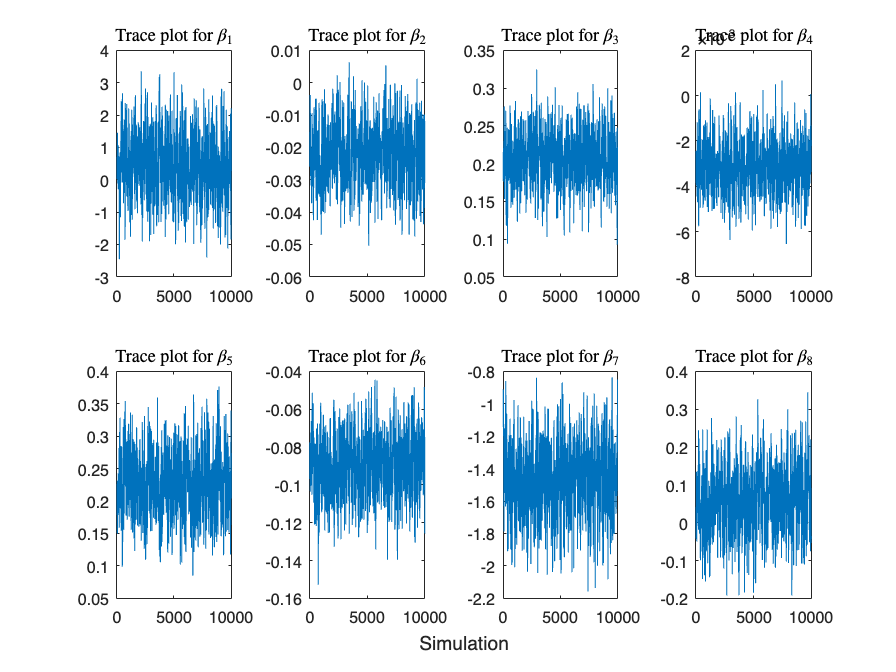

% Trace plots
figure
t = tiledlayout(2, 4);
for j = 1:p+1
    nexttile
    plot(beta_final(:, j))
    hold on
    title("Trace plot for $\beta_{" + j + "}$")
    hold off
end
xlabel(t, "Simulation")

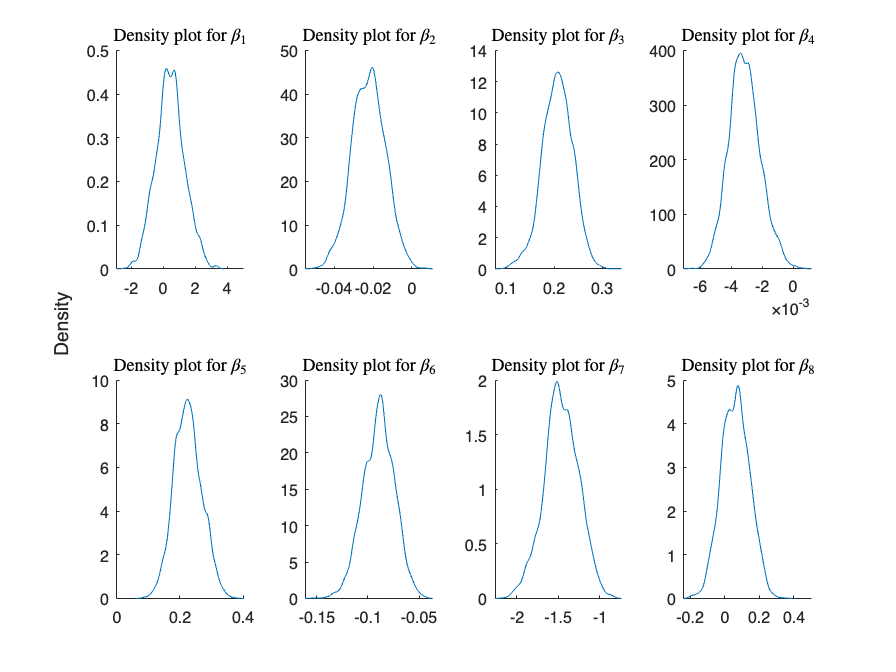

% Density plots
figure
t = tiledlayout(2, 4);
for j = 1:p+1
    nexttile
    hold on
    ksdensity(beta_final(:, j))
    hold off
    title("Density plot for $\beta_{" + j + "}$")
end
ylabel(t, "Density")

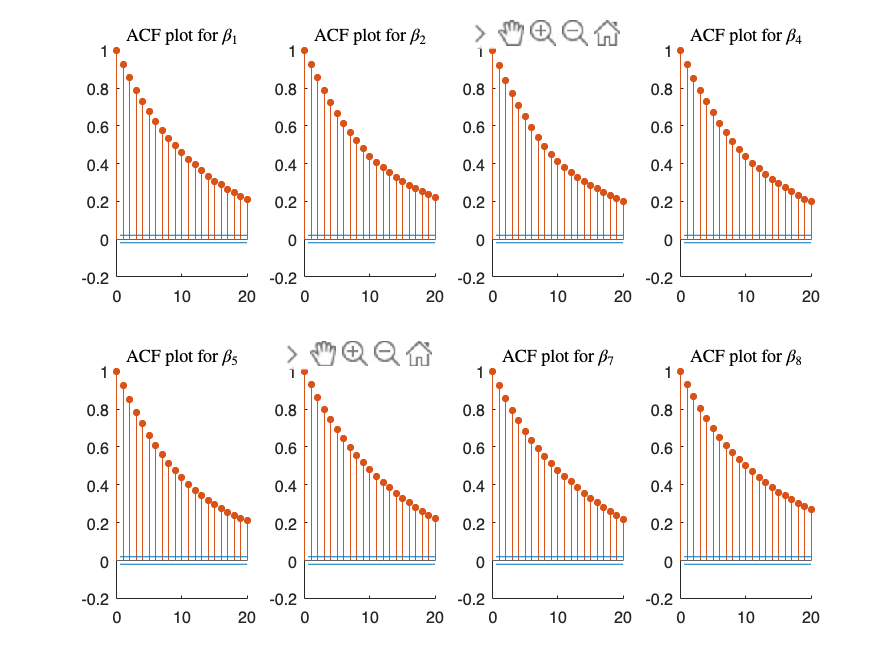

% Autocorrelation plots
figure
tiledlayout(2, 4);
for j = 1:p+1
    nexttile
    hold on
    autocorr(beta_final(:, j))
    hold off
    title("ACF plot for $\beta_{" + j + "}$")
end

**Trace plot:** Accoding to the trace plot, each $\beta_i$ is centered as some mean value the variations is also small. We think it converges to the stationary distribution.

**Density curve: **The density curve provides a smoothed representation of the distribution of sampled values. It helps visualize the shape of the distribution from which the samples are drawn. In our case, the posterior distribution is constructed by a logistic distribution as the likelihood and a normal distribution as the prior. We use a multivariate normal distribution as the proposal to approximate the posterior. A well-converged MCMC simulation should produce a density curve that closely represnets the true posterior distribution of the parameter being estimated. 

**ACF: **Based on the ACF plots, it seems we have autocorrelation among sampled values and the autocolaation decreaes as lag increases. Because we simulate throuth Metropolis-Hastings algorithm, the updated draws is related to the prvious iteration. Due to the correlation between samples, the sample chain usually exhibits some level of autocorrelation. 

**With **$\tau = 1$**: **After the MH algorithm, we receive a accept rate of 20.54% after running the MH algorithm 15,000 times, which means that roughly 1 out of every 5 proposed moves was accepted. The rest were rejected and the chain remained at its current state for those iterations. 

**Different value of **$\tau$**: **We also test with $\tau$= 0.1, 0.5, 0.9. The accept rate is 0.9289, 0.5089, 0.2377, respectively. It seems when $\tau$ is smaller, it is less likely to converge to the stationary distribution by trace plot.The ACF plot also shows a higher autocorrelation with a samller $\tau$. 

### Marginal Effects:

To have a better understanding of the effect of each $\beta_i$ on the outcome $y$ in the Trobit model, we need to take the marginal effects on our $\beta_i$.

% beta_MH is our matrix of posterior draws
% Each row in beta_MH is a draw from the posterior distribution
% Columns represent different coefficients

% X is our data matrix (excluding the dependent variable)
% Initialize matrix to store predicted probabilities
predicted_probs = zeros(size(X,1), size(beta_MH,1));

for i = 1:size(beta_MH,1)
    predicted_probs(:,i) = normcdf(X * beta_MH(i,:)');
end

% Initialize matrix to store marginal effects
marginal_effects = zeros(size(X,2), size(beta_MH,1));

for i = 1:size(beta_MH,1)
    % Calculate the linear predictor for this draw
    z = X * beta_MH(i,:)';
    % Calculate the PDF of the normal distribution at these values
    pdf_values = normpdf(z);
    % Calculate marginal effects for each variable
    for j = 1:size(X,2)
        marginal_effects(j,i) = mean(pdf_values .* X(:,j) * beta_MH(i,j));
    end
end

% Average the marginal effects across all draws
average_marginal_effects = mean(marginal_effects,2);
%print
marginal_beta = (average_marginal_effects)';
row = {'average_marginal_beta_effect'};
array2table(marginal_beta, 'RowNames', row)

ans = 1×8 table
                                    marginal_beta1    marginal_beta2    marginal_beta3    marginal_beta4    marginal_beta5    marginal_beta6    marginal_beta7    marginal_beta8
                                    ______________    ______________    ______________    ______________    ______________    ______________    ______________    ______________

    average_marginal_beta_effect       0.096933          -0.09898          0.42733          -0.097212          0.59289           -0.82805         -0.076516          0.01888    


**Explanation of each marginal effect βi on the probit model:**

Marginal effect of $\beta_1$ = 0.0969: The term beta1, which acts as the constant, with a marginal effect of 0.0969, sets the baseline probability of labor force participation when all the independent variables in the model are set to their reference levels or are zero. This marginal effect means that, in the absence of any specific influences from the variables included in the model (i.e., without considering factors like age, education, number of children, etc.), there is a baseline probability of 9.69% that a woman would be active in the labor force. The constant’s positive marginal effect establishes the starting point for analyzing labor force participation. It captures the effect of all unobserved factors not included in the model that could influence a woman's decision or ability to participate in the labor force. The value of 0.0969 as a baseline probability reflects the underlying likelihood of labor force participation given a neutral setting for all measured factors. From this base, each independent variable's effect is then added or subtracted to predict labor force participation more accurately. This foundational probability is crucial for understanding how adjustments in specific variables, such as the level of education or the presence of children, modify the likelihood of labor force activity from this initial benchmark.

Marginal effect of $\beta_2$ = -0.0990: In a logit model, where the dependent variable indicates whether a woman is currently active in the labor force, and an independent variable represents other sources of income aside from wage, a marginal effect of -0.990 means that as the income from sources other than wages increases  the probability of a woman participating in the labor force decreases by 9.90 percentage points, holding all other factors constant. This finding suggests that having alternative sources of income negatively impacts the likelihood of labor force participation among women. It implies that when women have financial income not tied to employment, they might be less inclined to seek or maintain employment, possibly due to reduced financial necessity or the appeal of other non-work-related activities and responsibilities.

Marginal effect of $\beta_3$ = 0.4273: The dependent variable is whether a woman is currently active in the labor force, the independent variable representing the level of education and its marginal effect of 0.4273 indicates a significant positive impact on labor force participation. This means that, holding all other factors constant, an increase in the level of education is associated with a 43.58 percentage point increase in the probability of a woman being active in the labor force. Essentially, this finding highlights education as a key driver in empowering women and enhancing their participation in the labor market.

Marginal effect of $\beta_4$ = -0.0972: In a logit model, where the dependent variable indicates whether a woman is currently active in the labor force, and one of the independent variables is years of experience, a marginal effect of -0.0972 for years of experience means that for each additional year of experience, the probability of a woman being active in the labor force decreases by 9.72 percentage points, holding all other variables constant. This suggests that as women gain more experience, there is a negative association with their likelihood of being active in the labor force. This could reflect various social, economic, or personal factors that influence a woman's participation in the labor force as her experience increases, such as career choices, family responsibilities, or retirement considerations. Also, as we will see later, the first years of a woman might align with having children under the age of 6 years old, thus confirming that there should be a negative correlation with years of experience and activity in the labor force.

Marginal effect of $\beta_5$ = 0.5929: In the logit model described, where the dependent variable captures whether a woman is currently active in the labor force and the independent variable is the square of years of experience, a marginal effect of 0.5929 implies that for each one-unit increase in the squared years of experience, the probability of a woman being active in the labor force increases by 59.29 percentage points, holding all other factors constant. This significant positive effect suggests a nonlinear relationship between years of experience and labor force participation. Initially, as experience increases, the likelihood of being active in the labor force may decrease (as indicated by a negative marginal effect for the linear term, if present). However, beyond a certain level of experience, further increases in experience (considering the squared term) lead to a substantial increase in the probability of labor force activity. This could reflect scenarios where women with substantial experience find or return to work due to various factors, such as achieving high-level positions, financial incentives, or personal fulfillment, illustrating a complex interaction between experience and labor force participation. It could also show a positive correlation between women gaining years of experience and having children between the ages of 6 and 18 years old (we will examine this independent variable later on), thus explaining that once children grow a bit and women gain more experience, they would return to the labor force.

Marginal effect of $\beta_6$ = -0.8281: The independent variable for age, with a marginal effect of -0.7667, indicates a significant negative influence on labor force participation. This marginal effect means that, holding all other variables constant, each additional year of age is associated with an 82.81 percentage point decrease in the probability of a woman being active in the labor market.

Marginal effect of $\beta_7$ = -0.0765: The independent variable representing the number of children less than 6 years old and its marginal effect of -0.0765 indicates a negative impact on labor force participation. Specifically, this means that for each additional child under the age of 6, the probability of a woman being active in the labor force decreases by 7.65 percentage points, holding all other factors constant. The finding suggests that having more young children at home is associated with a decrease in labor force activity among women, reflecting the challenges and choices women face in balancing work and family responsibilities.

Marginal effect of $\beta_8$ = 0.0189: In the same logit model examining whether a woman is currently active in the labor force, the independent variable for the number of children between 6 and 18 years old, with a marginal effect of 0.0189, reveals a positive impact on labor force participation. This indicates that, holding all other variables constant, for each additional child in the age range of 6 to 18, the probability of a woman being active in the labor market increases by 1.89 percentage points. This positive marginal effect suggests that the presence of older children, as opposed to younger ones, may have a less inhibiting or even slightly encouraging effect on a woman's decision or ability to participate in the labor force. Older children generally require less direct supervision and care than younger children, which could alleviate some of the childcare demands that constrain the labor force participation of women with younger children. This contrast highlights how the age of children influences the extent to which childcare responsibilities impact a woman's labor force activity. While younger children (less than 6 years old) tend to decrease labor force participation due to their intensive care needs, resulting in a -7.65 percentage points effect, older children may offer more flexibility or necessitate additional financial resources, slightly increasing participation by 1.89 percentage points. This differentiation underscores the dynamic nature of family responsibilities and their varying impact on employment decisions across different stages of motherhood and child-rearing.

## Additional:

An intuitive explanation of the process of how we obtained the maximum likelihood estimates for the logit model is based upon the following steps:

Step 1: Defining the Logit Model: The logit model, used for binary classification problems, models the probability that a binary response variable y equals 1 given a set of predictor variables x.

Step 2: Writing the Log-Likelihood function: Next, we define the log-likelihood function for the logit model so that by maximizing it, we are essentially calibrating the model so that its predicted probabilities for the binary outcome are as close as possible to the actual, observed outcomes.

Step 3: Computing the First Partial Derivatives: The first partial derivatives of the log-likelihood function with respect to the coefficients are needed to perform the optimization. These derivatives indicate the direction to adjust the parameters to increase the log-likelihood.

Step 4: Computing the Second Partial Derivatives (Hessian Matrix): The second partial derivatives of the log-likelihood function, or the Hessian matrix (H), give information about the curvature of the log-likelihood surface. This matrix is used in optimization algorithms to adjust the step size and direction when searching for the maximum likelihood estimates.

Step 5: Using an Optimization Algorithm: We started with an initial guess for the β coefficients. Using the current estimate of β, we calculate the gradient and Hessian matrix of the log-likelihood function. Then we update the estimate of β using the optimization algorithm. We repeat the iteration process until the change in the log-likelihood function (or in the β estimates) between iterations is smaller than a predetermined threshold, indicating convergence to the maximum likelihood estimates.

The analytical steps and the equations involed for the above explanation are the following:

The logistic regression likelihood function: 


$$p(y|x) = \prod_{i=1}^{n} [\frac{exp({x_i^{\top}{\beta})}} {1+exp(x_i^{\top}{\beta})}]^{y_i} [\frac{1} {1+exp(x_i^{\top}{\beta})}]^{1-y_i}$$


The log-likelihood function is the natural logarithm of the likelihood function: 


$$\text{log} p(y|x) = \sum_{i=1}^{n} [y_i \text{log}(\frac{exp({x_i^{\top}{\beta})}}{1+exp(x_i^{\top}{\beta})})+(1-y_i)log(\frac{1} {1+exp(x_i^{\top}{\beta})})] $$


                                                    
$$= \sum_{i=1}^{n} [ y_i x_i^{\top} \beta-y_i\text{log}(1+exp(x_i^{\top}{\beta})) + (1-y_i)\text{log}(1) - (1-y_i)\text{log}(1+exp(x_i^{\top}{\beta})) ]$$


        
$$= \sum_{i=1}^{n} [ y_i x_i^{\top} \beta-\text{log}(1+exp(x_i^{\top}{\beta})) ]$$
				

The first partial derivatives of the log-likelihood with respect to the elements of β: 


$$\frac{\partial(\text{log}(p(y|x)}{\partial{\beta}} = \sum_{i=1}^{n}(y_i-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})x_i$$


The Hessian matrix, denoted as H, is the matrix of the second partial derivatives of the log-likelihood with respect to the elements of β. 


$$H(\beta)=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} = -\sum_{i=1}^{n} x_ix_i^{\top}(1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$$


For a simplier notation:

$H(\beta)=\frac{\partial(\text{log}^2(p(y|x)}{\partial{\beta}^2} = -X^{\top}WX$,

where $W = (1-\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})(\frac{\text{exp}(x_i^{\top}\beta)}{1+\text{exp}(x_i^{\top}\beta)})$, and X is the independent variable.

function logPost = logPosterior(beta, X, y, B)
    % Logistic regression log-likelihood
    logLikelihood = sum(y .* (X * beta) - log(1 + exp(X * beta)));
    % Prior log-density
    logPrior = - (1 / 2) * beta' * inv(B) * beta;
    % Log posterior
    logPost = logLikelihood + logPrior;
end